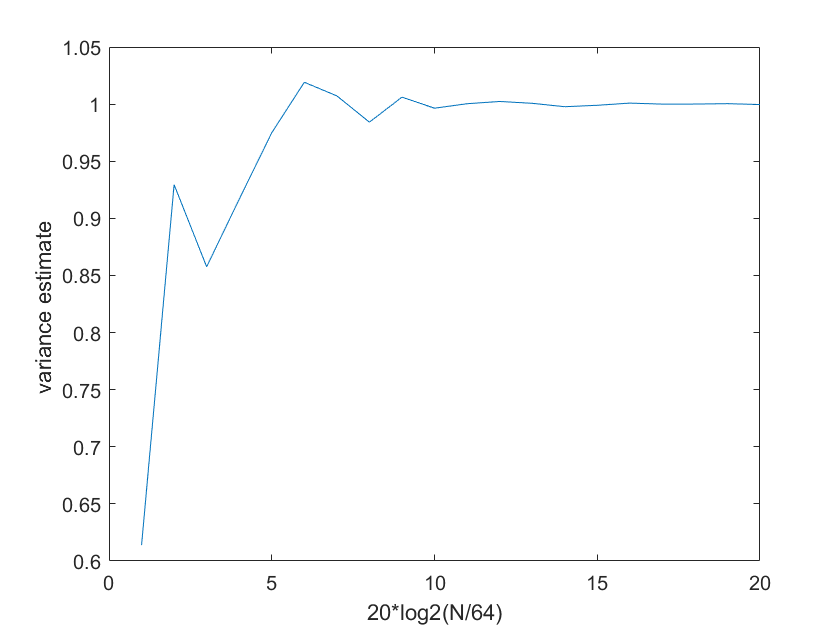


% Levinson Durbin Recursive algorithm
% LD algorithm is used for linear prediction filter coefficients
clc;
clear;
%Initialization of global parameters
M=3;    %Order of filter used
maxLen = 20; %Maximum length of white noise signal
variance =1 ; % variance of white noise signal

%Poles of the filter
%All poles are chosen to be within unit circle for STABILITY
p1=0.4;
p2=0.5;
p3=0.6;

%Finding filter coefficients as per given poles
a1 = -(p1+p2+p3);
a2 = (p1*p2+p2*p3+p3*p1);
a3 = -p1*p2*p3;

% AR parameters found b designed LD algorithm
alpha = zeros(maxLen,M+1);
% AR parameters found by Matlab inbuilt functions
alpha1 = zeros(maxLen,M+1);
% Reflection coefficients in designed LD algorithm
k = zeros(maxLen,M);
% Reflection coefficients in Matlab inbuilt functions
k1 = zeros(maxLen,M);
% Variance estimate in designed LD algorithm
err = zeros(maxLen,1);
% Variance estimate in Matlab inbuilt function
err1 = zeros(maxLen,1);
% Loop running across all possible lengths
for n=1:1:maxLen
    N = 128*2^(n-1); %length of the signal
    v = wgn(N,1,10*log10(variance)); %Noise signal with given specs
    %var(v)
    u1 = zeros(1,N+3)';
    for i=1:1:N
        %Code for AR process generatio
        u1(i+3) = -a1*u1(i+2)-a2*u1(i+1)-a3*u1(i)+v(i);
    end
    u=u1(4:N+3);
    Rx = zeros(M+1,1); %Autocorrelation Sequence
    for i=1:M+1
        for j=i+1:N+1
            Rx(i) = Rx(i) + u(j-1)*u(j-i);
        end
        Rx(i) = Rx(i)/(N-i+1);
    end
    temp = zeros(M,M); %Temporary filter coefficients variable
    E = zeros(M+1,1); %Temporary variance collecting variable
    total=0;
    
    %i=0 : zero level iteration
    E(1) = Rx(1); %Initializing estimates
    k(n,1) = -Rx(2)/Rx(1); %First reflection coefficient
    temp(1,1) = k(n,1); 
    E(2) = (1-(k(n,1))^2)*E(1); %First level variance estimate
    
    %Iteration or LD Recursion
    for i=2:1:M
        total=0;
        for j=1:1:i-1
            %dot product of autocorrelation sequence and filter
            %coefficients
            total = total + temp(i-1,j)*Rx(i+1-j);
        end
        k(n,i) = -(Rx(i+1)+total)/E(i); %Finding new reflection coefficients
        temp(i,i) = k(n,i); %Finding new filter coefficients
        for j=1:1:i-1
            %Updating lower order filter coefficients
            temp(i,j) = (temp(i-1,j)+k(n,i)*temp(i-1,i-j));
        end
        E(i+1) = (1-((k(n,i))^2))*E(i); %Updating variance estimates
    end
    
    alpha(n,:) = [1,temp(3,:)]; % final filter coefficients solution
    err(n) = E(M+1); %Final variance estimates
    %Using Matlab inbuilt Levinson Durbin Function
    [alpha1(n,:),err1(n),k1(n,:)] = levinson(Rx,3);
end
%Plotting the Results
figure
plot(1:1:maxLen, err); xlabel('20*log2(N/64)');
ylabel('variance estimate ');

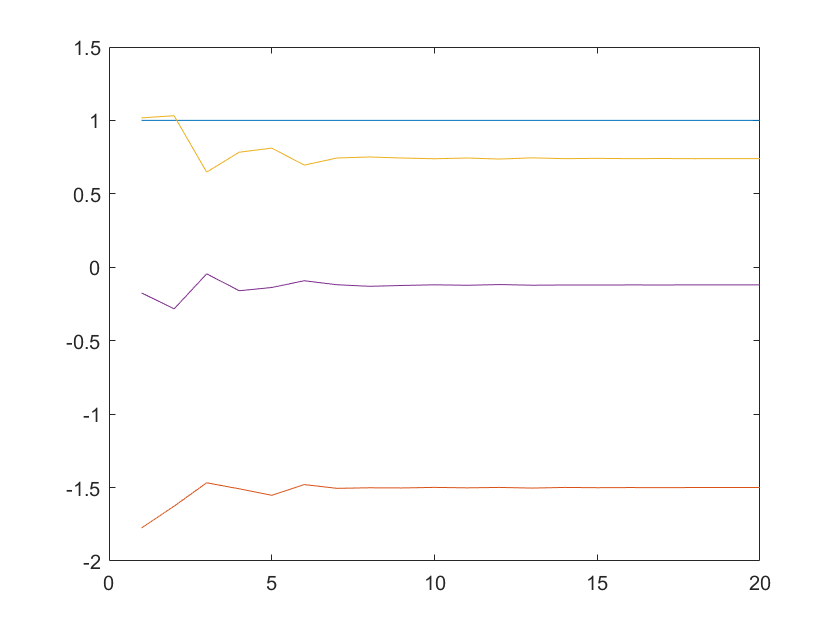

plot(alpha)

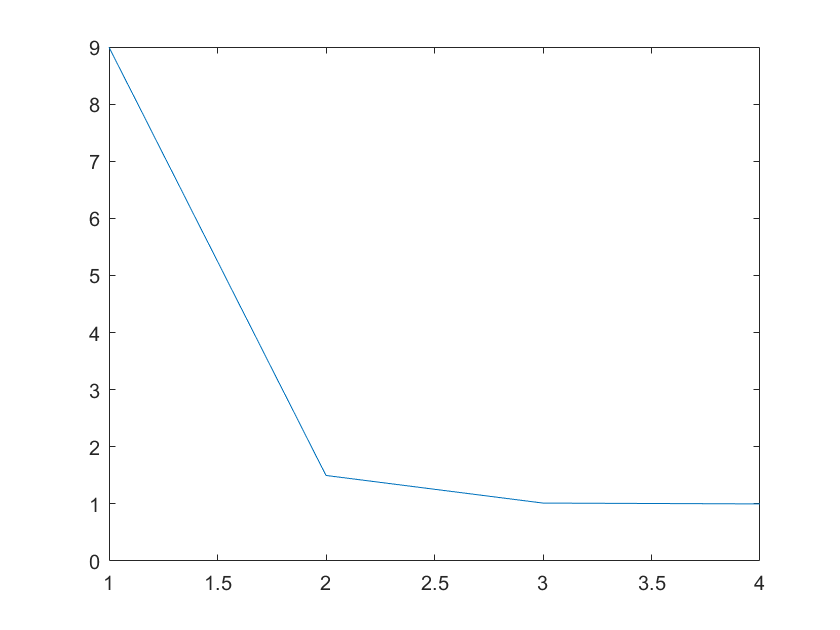

plot(E)